ECE 537 

Exercise #2

Group 5

Muqian Gui ----- V00870654

Hang Ruan ----- V00923058

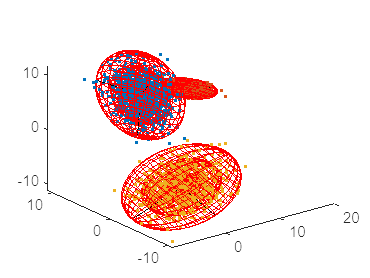

clc;
clear all;
close all;

% Reload data form Exercise 1
dim = 3; % Setdimension as 3 
K = 1000; % Number of data samples
u1 = [0 ; 4 ; 7]; % Mean for class A
u2 = [10 ; 5 ; 5]; % Mean for class B
u3 = [-2 ; -5 ; -5]; % Mean for class C
% Prescribed covariance matrix for class A
cov_matrix1 = [6.5 2.1651 1.25 ; 2.1651 5.125 2.3816 ; 1.25 2.3816 2.3750];
% Prescribed covariance matrix for class B
cov_matrix2 = [3.0184 0.4331 -1.4481; 0.4331 0.9436 -0.6456; -1.4481 -0.6456 1.2880];
% Prescribed covariance matrix for class C
cov_matrix3 = [6.8928 -1.3750 3.1945; -1.3750 3.3572 0.6945; 3.1945 0.6945 3.7500];

classA = dataGen_ContPlot(dim,K,u1,cov_matrix1);
classB = dataGen_ContPlot(dim,K,u2,cov_matrix2);
classC = dataGen_ContPlot(dim,K,u3,cov_matrix3);

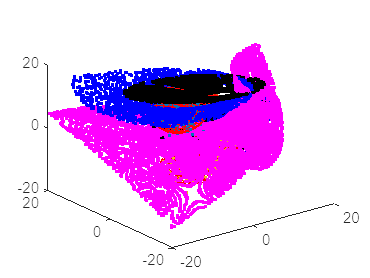

% Initial Decision Boundary for class A & B & C
[decBoundary_AB decBoundary_AC decBoundary_BC] = decision_boundary(u1,u2,u3,cov_matrix1,cov_matrix2,cov_matrix3,1/3,1/3,1/3);
decBoundary_t_AB = decBoundary_AB';
decBoundary_t_AC = decBoundary_AC';
decBoundary_t_BC = decBoundary_BC';
plot3(decBoundary_t_AB(:,1), decBoundary_t_AB(:,2), decBoundary_t_AB(:,3),'.','Color','k'); % Decision boundary for A & B is in black point
plot3(decBoundary_t_AC(:,1), decBoundary_t_AC(:,2), decBoundary_t_AC(:,3),'.','Color','m'); % Decision boundary for A & C is in pink point
plot3(decBoundary_t_BC(:,1), decBoundary_t_BC(:,2), decBoundary_t_BC(:,3),'.','Color','b'); % Decision boundary for B & C is in blue point

As the graph shown on the right(The larger scale of figure is saved as 'Result_Plotting_1'). The Bayes decision boundaries for equal priori class probabilities. 

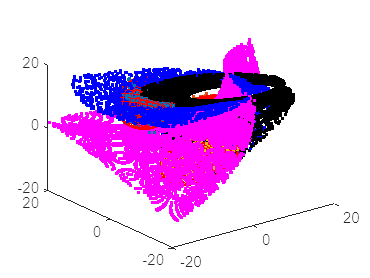

% Change of the mean for class A
u1 = [-6 ; 7 ; 9]; 
[decBoundary_AB decBoundary_AC decBoundary_BC] = decision_boundary(u1,u2,u3,cov_matrix1,cov_matrix2,cov_matrix3,1/3,1/3,1/3);
decBoundary_t_AB = decBoundary_AB';
decBoundary_t_AC = decBoundary_AC';
decBoundary_t_BC = decBoundary_BC';

figure
classA = dataGen_ContPlot(dim,K,u1,cov_matrix1);
classB = dataGen_ContPlot(dim,K,u2,cov_matrix2);
classC = dataGen_ContPlot(dim,K,u3,cov_matrix3);
plot3(decBoundary_t_AB(:,1), decBoundary_t_AB(:,2), decBoundary_t_AB(:,3),'.','Color','k'); % Decision boundary for A & B is in black point
plot3(decBoundary_t_AC(:,1), decBoundary_t_AC(:,2), decBoundary_t_AC(:,3),'.','Color','m'); % Decision boundary for A & C is in pink point
plot3(decBoundary_t_BC(:,1), decBoundary_t_BC(:,2), decBoundary_t_BC(:,3),'.','Color','b'); % Decision boundary for B & C is in blue point

As the graph shown on the right(The larger scale of figure is saved as 'Result_Plotting_2'). With change the mean vector of the class A. The contour of class A's position is shifted. The decision boundaries which indicated by the black and pink points also shifted with the change of mean vector.

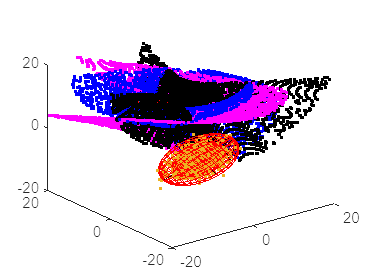

% Change of the covariance matrix for class A
u1 = [-6 ; 7 ; 9];
cov_matrix1 = [1.67 -1 -0.5; -1 2 -0.33; -0.5 -0.33 0.9167];
[decBoundary_AB decBoundary_AC decBoundary_BC] = decision_boundary(u1,u2,u3,cov_matrix1,cov_matrix2,cov_matrix3,1/3,1/3,1/3);
decBoundary_t_AB = decBoundary_AB';
decBoundary_t_AC = decBoundary_AC';
decBoundary_t_BC = decBoundary_BC';

figure
classA = dataGen_ContPlot(dim,K,u1,cov_matrix1);
classB = dataGen_ContPlot(dim,K,u2,cov_matrix2);
classC = dataGen_ContPlot(dim,K,u3,cov_matrix3);
plot3(decBoundary_t_AB(:,1), decBoundary_t_AB(:,2), decBoundary_t_AB(:,3),'.','Color','k'); % Decision boundary for A & B is in black point
plot3(decBoundary_t_AC(:,1), decBoundary_t_AC(:,2), decBoundary_t_AC(:,3),'.','Color','m'); % Decision boundary for A & C is in pink point
plot3(decBoundary_t_BC(:,1), decBoundary_t_BC(:,2), decBoundary_t_BC(:,3),'.','Color','b'); % Decision boundary for B & C is in blue point

As the graph shown on the right(The larger scale of figure is saved as 'Result_Plotting_3'). As the covariance matrix of class A is changed. The shape and orientation of class A is changed. The decision boundaries presented some changes on its shape, orientation and distinctness.

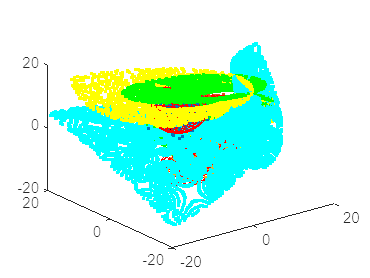

% Change of the priori probability for class A
u1 = [0 ; 4 ; 7];
cov_matrix1 = [6.5 2.1651 1.25 ; 2.1651 5.125 2.3816 ; 1.25 2.3816 2.3750];
[decBoundary_AB decBoundary_AC decBoundary_BC] = decision_boundary(u1,u2,u3,cov_matrix1,cov_matrix2,cov_matrix3,0.1,0.6,0.3);
decBoundary_t_AB = decBoundary_AB';
decBoundary_t_AC = decBoundary_AC';
decBoundary_t_BC = decBoundary_BC';

figure
classA = dataGen_ContPlot(dim,K,u1,cov_matrix1);
classB = dataGen_ContPlot(dim,K,u2,cov_matrix2);
classC = dataGen_ContPlot(dim,K,u3,cov_matrix3);
plot3(decBoundary_t_AB(:,1), decBoundary_t_AB(:,2), decBoundary_t_AB(:,3),'.','Color','g'); % Decision boundary for A & B is in black point
plot3(decBoundary_t_AC(:,1), decBoundary_t_AC(:,2), decBoundary_t_AC(:,3),'.','Color','c'); % Decision boundary for A & C is in pink point
plot3(decBoundary_t_BC(:,1), decBoundary_t_BC(:,2), decBoundary_t_BC(:,3),'.','Color','y'); % Decision boundary for B & C is in blue point

As the graph shown on the right(The larger scale of figure is saved as 'Result_Plotting_4'). There isn't any change when the prior probability changed. I didn't find out which parts wrong here. However, from my understanding, the change on the priori probabilities should shift the decision boundaries to favor or disfavor certain classes. For example, if the priori probability of class A increases, the decision boundary should shift towards class A which will increasing the likelihood of classfying the data into class A. But it didn't show on the resulting plot. There must be something wrong with the code and I just didn't find it out.

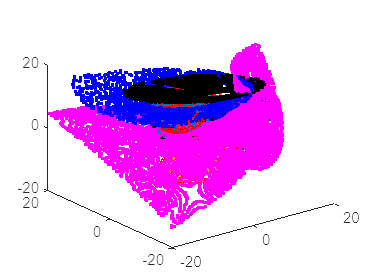

% Decision boundaries with risk discriminant funciton

[decBoundary_AB decBoundary_AC decBoundary_BC] = risk_decision_boundary(1,0,0,1,0,1,u1,u2,u3,cov_matrix1,cov_matrix2,cov_matrix3,1/3,1/3,1/3);
decBoundary_t_AB = decBoundary_AB';
decBoundary_t_AC = decBoundary_AC';
decBoundary_t_BC = decBoundary_BC';

figure
classA = dataGen_ContPlot(dim,K,u1,cov_matrix1);
classB = dataGen_ContPlot(dim,K,u2,cov_matrix2);
classC = dataGen_ContPlot(dim,K,u3,cov_matrix3);
plot3(decBoundary_t_AB(:,1), decBoundary_t_AB(:,2), decBoundary_t_AB(:,3),'.','Color','k'); % Decision boundary for A & B is in black point
plot3(decBoundary_t_AC(:,1), decBoundary_t_AC(:,2), decBoundary_t_AC(:,3),'.','Color','m'); % Decision boundary for A & C is in pink point
plot3(decBoundary_t_BC(:,1), decBoundary_t_BC(:,2), decBoundary_t_BC(:,3),'.','Color','b'); % Decision boundary for B & C is in blue point

As the graph shown on the right(The larger scale of figure is saved as 'Result_Plotting_5'). The plotting is exactly same as the first graph obtained. Therefore, the decision boundary for zero-one loss presented the same result as the bayes classifier based on posterior probability.

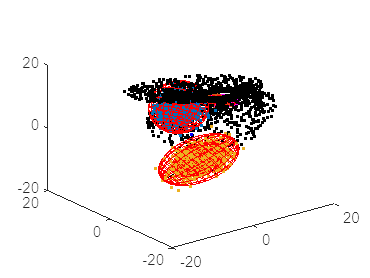

% Decision boundaries with risk discriminant funciton increasing lamda AB

[decBoundary_AB decBoundary_AC decBoundary_BC] = risk_decision_boundary(1,5,0,1,0,1,u1,u2,u3,cov_matrix1,cov_matrix2,cov_matrix3,1/3,1/3,1/3);
decBoundary_t_AB = decBoundary_AB';
decBoundary_t_AC = decBoundary_AC';
decBoundary_t_BC = decBoundary_BC';

figure
classA = dataGen_ContPlot(dim,K,u1,cov_matrix1);
classB = dataGen_ContPlot(dim,K,u2,cov_matrix2);
classC = dataGen_ContPlot(dim,K,u3,cov_matrix3);
plot3(decBoundary_t_AB(:,1), decBoundary_t_AB(:,2), decBoundary_t_AB(:,3),'.','Color','k'); % Decision boundary for A & B is in black point
plot3(decBoundary_t_AC(:,1), decBoundary_t_AC(:,2), decBoundary_t_AC(:,3),'.','Color','m'); % Decision boundary for A & C is in pink point
plot3(decBoundary_t_BC(:,1), decBoundary_t_BC(:,2), decBoundary_t_BC(:,3),'.','Color','b'); % Decision boundary for B & C is in blue point

As the graph shown on the right(The larger scale of figure is saved as 'Result_Plotting_6'). As the lamda AB increasing, the decision boundaries moving away from class C. The region volume of class C significantly increasing. Which means more points will be likely to be classfied as class C. While increasing the lamda AC or lamda BC will resulting the similar change on decision boundaries. Increaing on lamda AC will resulting larger volume of class B and increasing on lamda BC will resulting larger volume of class A

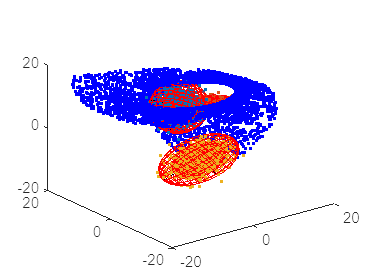

% Decision boundaries with risk discriminant funciton decreasing lamda AA

[decBoundary_AB decBoundary_AC decBoundary_BC] = risk_decision_boundary(-2,0,0,1,0,1,u1,u2,u3,cov_matrix1,cov_matrix2,cov_matrix3,1/3,1/3,1/3);
decBoundary_t_AB = decBoundary_AB';
decBoundary_t_AC = decBoundary_AC';
decBoundary_t_BC = decBoundary_BC';

figure
classA = dataGen_ContPlot(dim,K,u1,cov_matrix1);
classB = dataGen_ContPlot(dim,K,u2,cov_matrix2);
classC = dataGen_ContPlot(dim,K,u3,cov_matrix3);
plot3(decBoundary_t_AB(:,1), decBoundary_t_AB(:,2), decBoundary_t_AB(:,3),'.','Color','k'); % Decision boundary for A & B is in black point
plot3(decBoundary_t_AC(:,1), decBoundary_t_AC(:,2), decBoundary_t_AC(:,3),'.','Color','m'); % Decision boundary for A & C is in pink point
plot3(decBoundary_t_BC(:,1), decBoundary_t_BC(:,2), decBoundary_t_BC(:,3),'.','Color','b'); % Decision boundary for B & C is in blue point

As the graph shown on the right(The larger scale of figure is saved as 'Result_Plotting_7'). The negative loss will decrease the risk of selecting class A in this case and the classification region for class A will grow as shown in the plot. This also appied on change the lamda BB & lamda CC.

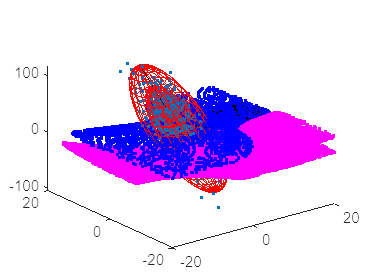

% Influence of outlier data point
rng(0);
% Generate the outlier data point to class A at 10, 50 , 100 standard deviation
sd = [10, 50, 100];  
outlier_data = Mahalanobis_distance(u1,cov_matrix1,sd);
sd_10 = outlier_data(:,2);
sd_50 = outlier_data(:,3);
sd_100 = outlier_data(:,4);

data_A = dataGeneratorFunc(dim,K,u1,cov_matrix1); % Data generated for class A
data2_B = dataGeneratorFunc(dim,K,u2,cov_matrix2); % Data generated for class B
data3_C = dataGeneratorFunc(dim,K,u3,cov_matrix3); % Data generated for class C

new_data_A = [data_A;sd_10';sd_50';sd_100'];
u_new = mean(new_data_A)';
cov_new = cov(new_data_A);

[decBoundary_AB decBoundary_AC decBoundary_BC] = decision_boundary(u_new,u2,u3,cov_new,cov_matrix2,cov_matrix3,1/3,1/3,1/3);
decBoundary_t_AB = decBoundary_AB';
decBoundary_t_AC = decBoundary_AC';
decBoundary_t_BC = decBoundary_BC';

figure
classA = dataGen_ContPlot(dim,K,u_new,cov_new);
classB = dataGen_ContPlot(dim,K,u2,cov_matrix2);
classC = dataGen_ContPlot(dim,K,u3,cov_matrix3);
plot3(decBoundary_t_AB(:,1), decBoundary_t_AB(:,2), decBoundary_t_AB(:,3),'.','Color','k'); % Decision boundary for A & B is in black point
plot3(decBoundary_t_AC(:,1), decBoundary_t_AC(:,2), decBoundary_t_AC(:,3),'.','Color','m'); % Decision boundary for A & C is in pink point
plot3(decBoundary_t_BC(:,1), decBoundary_t_BC(:,2), decBoundary_t_BC(:,3),'.','Color','b'); % Decision boundary for B & C is in blue point

As the graph shown on the right(The larger scale of figure is saved as 'Result_Plotting_8'). Aafter adding the outlier data points to class A. There isn't too much change on the mean vector for class A. But the covariance matrix presented a significant change. Which leading the inter-class Bayes decision boundaries' shape significantly changed.

a): Yes, the nature of class decision boundaries can be influenced by only few data points. The decision boundaries in classification are determined based on teh distribution of the available data points for each class. Just like the result obtained above, the outlier points significantly deviate from the majority of the data. Which resulted pulling the decision boundary toward class A. This will leading misclassification.

b): It's not appropriate to have decision boundaries that highly sensitive to small number of data samples. It should have decision boundaries to generalize well to unseen data so it will not be influenced by small number of data sample.

c): There are couple ways to detect this issue. One is to identify outliers of data set. Other method like to visualize the decision boundaries and examine the behaviour related to the data points. Also can use the cross-validation to evaluate the model's performance on different subsets of data to see if the performance changed significantly for different subset data. 

d): To resolve this issue, we can use regularization techniques or applying appropriate data preprocessing techniques like outliers removal, feature scaling or normalization. depend on the characteristics of the data, choosing appropriate algorithm will also help. With using these method combination based on differnet scenario, try to obtain the optimal data sets which will present consistent performance.

function [AB AC BC] = decision_boundary(u1,u2,u3,cov_matrix1,cov_matrix2,cov_matrix3,p1,p2,p3)

vol = vol3D([-20 20 -20 20 -20 20], 300);
s = size(vol,1);
decBoundary_12 = zeros(3,1); % Initial set up for decision Boundary for class A & class B
decBoundary_13 = zeros(3,1); % Initial set up for decision Boundary for class A & class C
decBoundary_23 = zeros(3,1); % Initial set up for decision Boundary for class B & class C
vol_t = vol';

w1_1 = -0.5*inv(cov_matrix1);
w2_1 = inv(cov_matrix1)*u1;
w3_1 = -0.5*u1'*inv(cov_matrix1)*u1-0.5*log(det(cov_matrix1))+log(p1);

w1_2 = -0.5*inv(cov_matrix2);
w2_2 = inv(cov_matrix2)*u2;
w3_2 = -0.5*u2'*inv(cov_matrix2)*u2-0.5*log(det(cov_matrix2))+log(p2);
 
w1_3 = -0.5*inv(cov_matrix3);
w2_3 = inv(cov_matrix3)*u3;
w3_3 = -0.5*u3'*inv(cov_matrix3)*u3-0.5*log(det(cov_matrix3))+log(p3);


for i = 1:s

    g_1 = vol_t(:,i)'*w1_1*vol_t(:,i) + w2_1'*vol_t(:,i) + w3_1;
    g_2 = vol_t(:,i)'*w1_2*vol_t(:,i) + w2_2'*vol_t(:,i) + w3_2;
    g_3 = vol_t(:,i)'*w1_3*vol_t(:,i) + w2_3'*vol_t(:,i) + w3_3;

    if (  abs(g_1 - g_2)<0.05 )
    
        decBoundary_12 = [decBoundary_12 vol_t(:,i)];
    else
        decBoundary_12 = decBoundary_12;
       
    end

    if (  abs(g_1 - g_3)<0.05 )
    
        decBoundary_13 = [decBoundary_13 vol_t(:,i)];
    else
        decBoundary_13 = decBoundary_13;
       
    end

    if (  abs(g_3 - g_2)<0.05 )
    
        decBoundary_23 = [decBoundary_23 vol_t(:,i)];
    else
        decBoundary_23 = decBoundary_23;
       
    end

end
AB = decBoundary_12;
AC = decBoundary_13;
BC = decBoundary_23;
end

function [AB AC BC] = risk_decision_boundary(lam_AA,lam_AB,lam_AC,lam_BB,lam_BC,lam_CC,u1,u2,u3,cov_matrix1,cov_matrix2,cov_matrix3,p1,p2,p3)

vol = vol3D([-20 20 -20 20 -20 20], 300);
s = size(vol,1);
decBoundary_12 = zeros(3,1); % Initial set up for decision Boundary for class A & class B
decBoundary_13 = zeros(3,1); % Initial set up for decision Boundary for class A & class C
decBoundary_23 = zeros(3,1); % Initial set up for decision Boundary for class B & class C
vol_t = vol';

w1_1 = -0.5*inv(cov_matrix1);
w2_1 = inv(cov_matrix1)*u1;
w3_1 = -0.5*u1'*inv(cov_matrix1)*u1-0.5*log(det(cov_matrix1))+log(p1);

w1_2 = -0.5*inv(cov_matrix2);
w2_2 = inv(cov_matrix2)*u2;
w3_2 = -0.5*u2'*inv(cov_matrix2)*u2-0.5*log(det(cov_matrix2))+log(p2);
 
w1_3 = -0.5*inv(cov_matrix3);
w2_3 = inv(cov_matrix3)*u3;
w3_3 = -0.5*u3'*inv(cov_matrix3)*u3-0.5*log(det(cov_matrix3))+log(p3);


for i = 1:s

    g_1 = vol_t(:,i)'*w1_1*vol_t(:,i) + w2_1'*vol_t(:,i) + w3_1;
    g_2 = vol_t(:,i)'*w1_2*vol_t(:,i) + w2_2'*vol_t(:,i) + w3_2;
    g_3 = vol_t(:,i)'*w1_3*vol_t(:,i) + w2_3'*vol_t(:,i) + w3_3;

    r_1 = lam_AA*g_1+lam_AB*g_2+lam_AC*g_3;
    r_2 = lam_AB*g_1+lam_BB*g_2+lam_BC*g_3;
    r_3 = lam_AC*g_1+lam_BC*g_2+lam_CC*g_3;


    if (  abs(r_1 - r_2)<0.05 )
    
        decBoundary_12 = [decBoundary_12 vol_t(:,i)];
    else
        decBoundary_12 = decBoundary_12;
       
    end

    if (  abs(r_1 - r_3)<0.05)
    
        decBoundary_13 = [decBoundary_13 vol_t(:,i)];
    else
        decBoundary_13 = decBoundary_13;
       
    end

    if (  abs(r_3 - r_2)<0.05 )
    
        decBoundary_23 = [decBoundary_23 vol_t(:,i)];
    else
        decBoundary_23 = decBoundary_23;
       
    end

end
AB = decBoundary_12;
AC = decBoundary_13;
BC = decBoundary_23;
end


function outlierPoints = Mahalanobis_distance(u,cov,sd)

outlierPoints = zeros(3,1);

for i = 1:length(sd)

    desired_std_dev = sd(i);
    [~, eig_vals] = eig(cov);
    scaling_factor = sqrt(diag(eig_vals)) * desired_std_dev;        
    random_vector = randn(size(u));      
    scaled_vector = scaling_factor .* random_vector;    
    mahalanobis_point = u + scaled_vector;
    outlierPoints = [outlierPoints mahalanobis_point];

end
end


function result = dataGen_ContPlot(dim,K,u,cov_matrix)
   
    data = randn(K,dim);
    data = data-mean(data,1);
    data = data/chol(cov(data));
    data = data*chol(cov_matrix); 
    data = data+u';

    [x,y,z] = ellipsoid(0,0,0,1,1,1);
    p = [x(:) y(:) z(:)]';
    [v,d]=eig(cov_matrix);
    d_1 = 1 * sqrt(d);
    d_2 = 2 * sqrt(d);
    d_3 = 3 * sqrt(d);
    b_1 = (v*d_1*p) + repmat(u, 1, size(p,2)); 
    x_1 = reshape(b_1(1,:), size(x));
    y_1 = reshape(b_1(2,:), size(y));
    z_1 = reshape(b_1(3,:), size(z));
    b_2 = (v*d_2*p) + repmat(u, 1, size(p,2)); 
    x_2 = reshape(b_2(1,:), size(x));
    y_2 = reshape(b_2(2,:), size(y));
    z_2 = reshape(b_2(3,:), size(z));
    b_3 = (v*d_3*p) + repmat(u, 1, size(p,2)); 
    x_3 = reshape(b_3(1,:), size(x));
    y_3 = reshape(b_3(2,:), size(y));
    z_3 = reshape(b_3(3,:), size(z));
    x1 = [u(1,:),x_3(21,1)];
    y1 = [u(2,:) y_3(21,1)];
    z1 = [u(3,:) z_3(21,1)];
    x2 = [u(1,:),x_3(11,11)];
    y2 = [u(2,:) y_3(11,11)];
    z2 = [u(3,:) z_3(11,11)];
    x3 = [u(1,:),x_3(11,16)];
    y3 = [u(2,:) y_3(11,16)];
    z3 = [u(3,:) z_3(11,16)];


    plot3(data(:,1), data(:,2), data(:,3),'.');
    hold on
    surf(x_1,y_1,z_1,'EdgeColor',[1 0 0],FaceAlpha=0.0001);
    surf(x_2,y_2,z_2,'EdgeColor',[1 0 0],FaceAlpha=0.0001);
    surf(x_3,y_3,z_3,'EdgeColor',[1 0 0],FaceAlpha=0.0001);
    line(x1,y1,z1,'Color','black','LineStyle','-');
    line(x2,y2,z2,'Color','black','LineStyle','-');
    result  = line(x3,y3,z3,'Color','black','LineStyle','-');


end

function data = dataGeneratorFunc(dim,K,u,cov_matrix)
    data = randn(K,dim);
    data = data-mean(data,1);
    data = data/chol(cov(data));
    data = data*chol(cov_matrix); 
    data = data+u';
end

